%load starData
nObs = size(spectra,1)

nObs = 357

lambdaStart = 630.02

lambdaStart = 630.0200

lambdaDelta = 0.14

lambdaDelta = 0.1400

lambdaEnd = lambdaStart + (nObs-1)*lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart:lambdaDelta:lambdaEnd)

lambda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800


s = spectra

s = 1.0e-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


plot(lambda,s,".-")
xlabel("Wavelength")
ylabel("Intensity")
[sHa,idx] = min(s)

sHa = 1.0e-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690    0.0980    0.0221


idx =    188   187   188   189   189   191   185


lambdaHa = lambda(idx)

lambdaHa =   656.2000  656.0600  656.2000  656.3400  656.3400  656.6200  655.7800


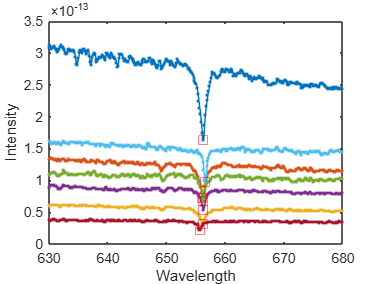

hold on
plot(lambdaHa, sHa, "rs", "MarkerSize", 8)
hold off

z = lambdaHa/656.28 - 1

z = 1.0e-03 *

   -0.1219   -0.3352   -0.1219    0.0914    0.0914    0.5181   -0.7619


speed = z*299792.458

speed =   -36.5445 -100.4973  -36.5445   27.4083   27.4083  155.3139 -228.4029


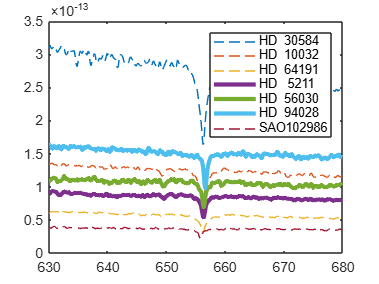

for v = 1:7
    s = spectra(:,v);
    if speed(v) <= 0
        plot(lambda,s,"--")
        else
        plot(lambda,s,LineWidth=3) 
    end
    hold on
end
hold off
legend(starnames)

movaway = starnames(speed > 0) 

movaway = 3x1 string array
    "HD   5211"
    "HD  56030"
    "HD  94028"
